m=mobiledev

m = mobiledev with properties:

                      Device: 'Galaxy A52s 5G'
                   Connected: 1
            AvailableCameras: {'back' 'front'}
                     Logging: 0
            InitialTimestamp: ''

   AccelerationSensorEnabled: 0
AngularVelocitySensorEnabled: 1
       MagneticSensorEnabled: 1
    OrientationSensorEnabled: 1
       PositionSensorEnabled: 0

Supported functions

m.AccelerationSensorEnabled = 1;
m.Logging = 1;


m.Logging = 0;

%m.AccelerationSensorEnabled = 0;


[a, t] = accellog(m);
[o, t2]=orientlog(m);

for i= 1:length(t)
    if (abs(a(i,1))<0.2)
        a(i,1)=0;
    end
    if (abs(a(i,2))<0.2)
        a(i,2)=0;
    end
end

window = 7;
h = normpdf( -window:window, 0, fix((2*window+1)/6) );
filterAX = filter(h, 1, a(:,1));
filterAY = filter(h, 1, a(:,2));
% plot(916), plot( y ), set(gca, 'YLim', [-1 1], 'xtick',[])
% title('gaussian')

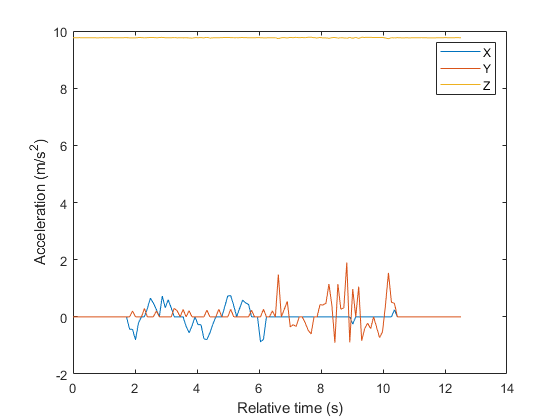

plot(t, a);
legend('X', 'Y', 'Z');
xlabel('Relative time (s)');
ylabel('Acceleration (m/s^2)');

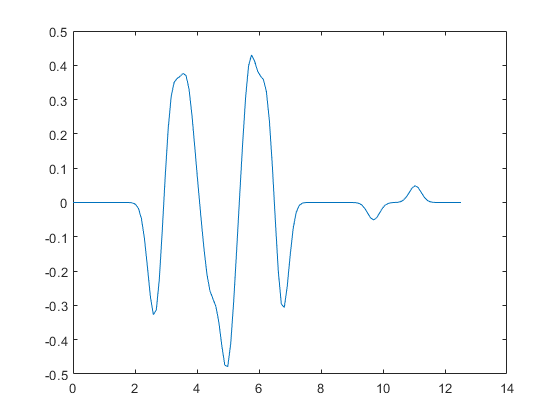

plot(t, filterAX);

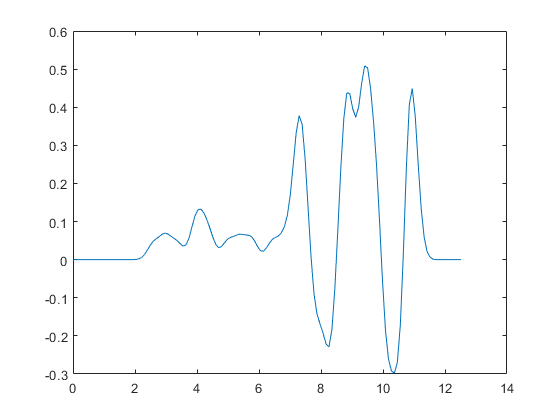

plot(t, filterAY);

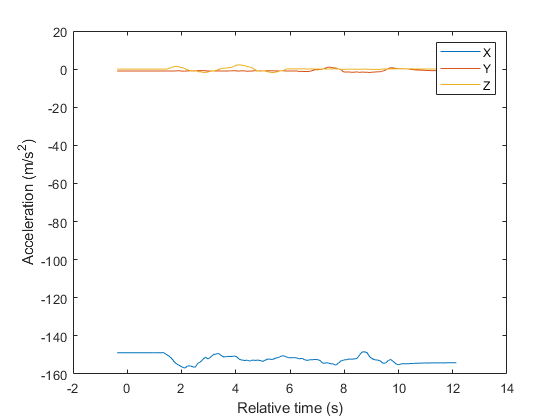

plot(t2, o);
legend('X', 'Y', 'Z');
xlabel('Relative time (s)');
ylabel('Acceleration (m/s^2)');


% t(end)
% length(t)
% a(1,2)

for i= 1:length(t)
    if i==1        
         vx(i)= 0+a(i,1)*(t(end)/length(t));
         vy(i)= 0+a(i,2)*(t(end)/length(t));
    else
        vx(i)= vx(i-1)+a(i,1)*(t(end)/length(t));
        vy(i)= vy(i-1)+a(i,2)*(t(end)/length(t));
    end
end
for i= 1:length(t)
    if (abs(vx(i))<0.01)
        vx(i)=0;
    elseif(abs(vy(i))<0.01)
        vy(i)=0;
    end
end

plot(t, vx);hold

현재 플롯이 유지됨


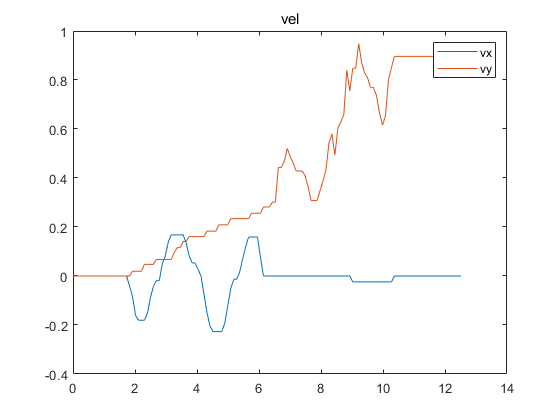

plot(t, vy);hold off
legend('vx', 'vy');
title('vel')


for i= 1:length(t)
    if i==1
        filtervx(i)= 0+filterAX(i)*(t(end)/length(t));
        filtervy(i)= 0+filterAY(i)*(t(end)/length(t));
    else
        filtervx(i)= filtervx(i-1)+filterAX(i)*(t(end)/length(t));
        filtervy(i)= filtervy(i-1)+filterAY(i)*(t(end)/length(t));
    end
end

for i= 1:length(t)
    if (abs(filtervx(i))<0.01)
        filtervx(i)=0;
    elseif(abs(filtervy(i))<0.01)
        filtervy(i)=0;
    end
end

plot(t, filtervx);hold

현재 플롯이 유지됨


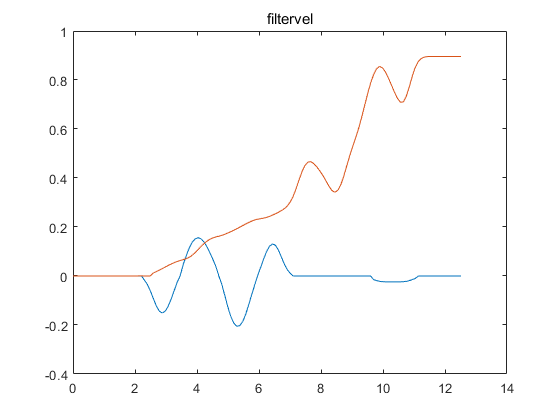

plot(t, filtervy);hold off
title('filtervel')

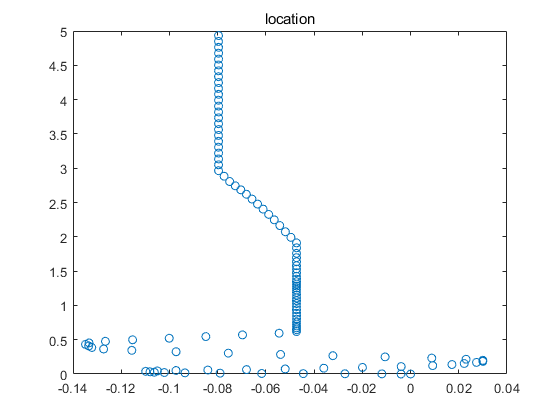


for i= 1:length(t)
    if i==1
        px(i)= 0+vx(i)*(t(end)/length(t));%*deg2rad(o(i,1));
        py(i)= 0+vy(i)*(t(end)/length(t));%*deg2rad(o(i,1));
    else
        px(i)= px(i-1)+vx(i)*(t(end)/length(t));%*deg2rad(o(i,1));
        py(i)= py(i-1)+vy(i)*(t(end)/length(t));%*deg2rad(o(i,1));
    end

end
plot(px,py,'o')
title("location")

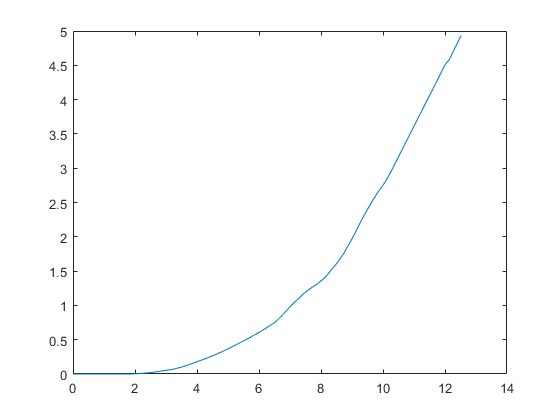

plot(t,py)

lotation=[px ; py]

lotation =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   -0.0040   -0.0119   -0.0272   -0.0445   -0.0618   -0.0790   -0.0936   -0.1021   -0.1063   -0.1081   -0.1099   -0.1050   -0.0973   -0.0841   -0.0680   -0.0520   -0.0360   -0.0199   -0.0039    0.0092    0.0172    0.0223    0.0274    0.0300    0.0300    0.0230    0.0088   -0.0106   -0.0322   -0.0539   -0.0756
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0019    0.0037    0.0056    0.0074    0.0120    0.0166    0.0211    0.0257    0.0321    0.0385    0.0450    0.0514    0.0578    0.0643    0.0734    0.0845    0.0955    0.1090    0.1224    0.1378    0.1532    0.1685    0.1839    0.1993    0.2147    0.2322    0.2497    0.2672    0.28

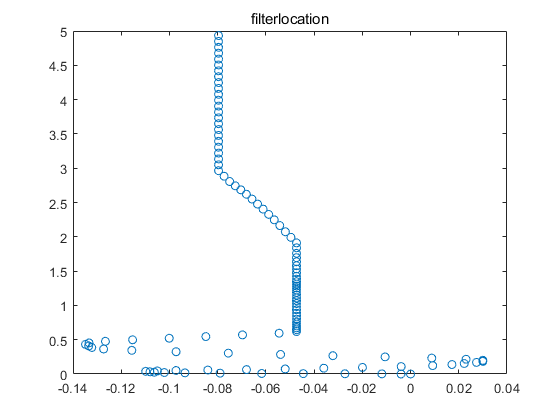


for i= 1:length(t)
    if i==1
        filterpx(i)= 0+filtervx(i)*(t(end)/length(t));%*deg2rad(o(i,1));
        filterpy(i)= 0+filtervy(i)*(t(end)/length(t));%*deg2rad(o(i,1));
    else
        filterpx(i)= filterpx(i-1)+vx(i)*(t(end)/length(t));%*deg2rad(o(i,1));
        filterpy(i)= filterpy(i-1)+vy(i)*(t(end)/length(t));%*deg2rad(o(i,1));
    end
end
plot(filterpx,filterpy,'o')
title("filterlocation")

plot(t,filterpy)

filterlotation=[filterpx;filterpy]

filterlotation =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   -0.0040   -0.0119   -0.0272   -0.0445   -0.0618   -0.0790   -0.0936   -0.1021   -0.1063   -0.1081   -0.1099   -0.1050   -0.0973   -0.0841   -0.0680   -0.0520   -0.0360   -0.0199   -0.0039    0.0092    0.0172    0.0223    0.0274    0.0300    0.0300    0.0230    0.0088   -0.0106   -0.0322   -0.0539   -0.0756
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0019    0.0037    0.0056    0.0074    0.0120    0.0166    0.0211    0.0257    0.0321    0.0385    0.0450    0.0514    0.0578    0.0643    0.0734    0.0845    0.0955    0.1090    0.1224    0.1378    0.1532    0.1685    0.1839    0.1993    0.2147    0.2322    0.2497    0.2672  


plot(t2, o);
legend('X', 'Y', 'Z');
xlabel('Relative time (s)');
ylabel('Acceleration (m/s^2)');

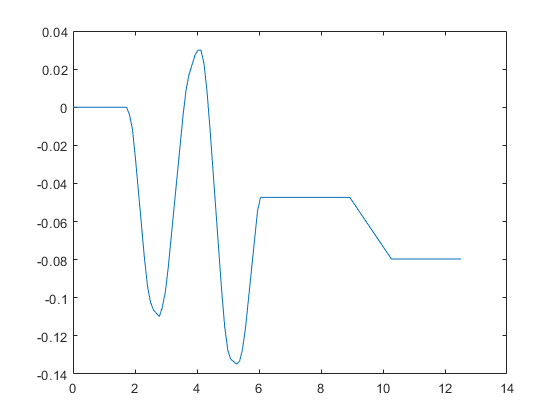

plot(t,px)

plot(t,filterpx)

m.AccelerationSensorEnabled = 0;

clear m;




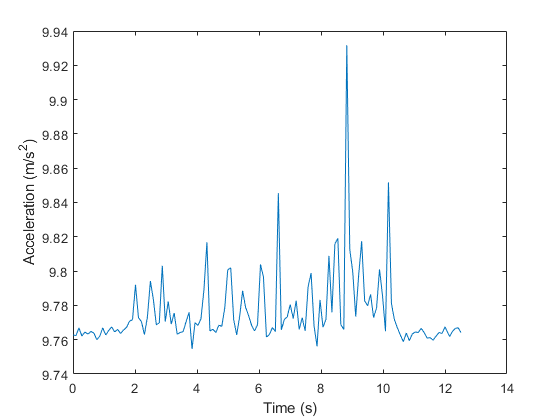

x = a(:,1);
y = a(:,2);
z = a(:,3);

% Calculate and plot magnitude.
mag = sqrt(sum(x.^2 + y.^2 + z.^2, 2));
plot(t, mag);
xlabel('Time (s)');
ylabel('Acceleration (m/s^2)');

m.Acceleration(1)

이름 m.Acceleration을(를) 확인할 수 없습니다.

 
velocity.X = cumtrapz(1/10,acceleration.X/1000*9.81);
volocity.Y = cumtrapz(1/10,acceleration.Y/1000*9.81);
velocity.Z = cumtrapz(1/10,acceleration.Z/1000*9.81);
position.X = trapz(1/10,velocity.X);
position.Y = trapz(1/10,velocity.Y);
position.Z = trapz(1/10,velocity.Z);